% Point in which the simulation have been check are
% P1 = [-3.54; 0];  / [-5, 0]   / [0, 0]  
% P2 = [0; -3.54];  / [0, 0 ]   / [0, -5]
% omega1 = omega    / omega     / omega
% omega2 = omega    / omega     / -omega

% Hyperparameters
r = 2.5;         % Radius of the circles
v = 5;
omega = 1;       % Angular velocity
v1 = v;
v2 = v;
omega1 = omega;
omega2 = omega;

r_turn = v/omega;      % Radius of curvature

T = pi / omega;  % Duration of the simulation for half a circle
dt = 0.1;        % Time step

% Initial points
% should be taken in the point in which 
% the aircraft collide from main script
P1 = [-3.54; 0];    % Blue aircraft
P2 = [0; -3.54];    % Red aircraft

% Centers of the circles
center1 = P1 + [r_turn; 0]; % Center for the blue aircraft safezone
center2 = P2 + [0; r_turn]; % Center for the red aircraft safezone

% Setup the figure for plotting
figure;
subplot(1, 2, 1); 
hold on;
axis equal;
xlim([-10 10]);
ylim([-10 10]);
grid on;

% Generate the circle points
theta = linspace(0, 2*pi, 100); % discretizing cirlcle
x_circle = r * cos(theta);
y_circle = r * sin(theta);

% creating object
a1 = plot(P1(1), P1(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Blue aircraft
a2 = plot(P2(1), P2(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Red aircraft
c1 = plot(P1(1) + x_circle, P1(2) + y_circle, 'b'); % Initial circle for blue aircraft
c2 = plot(P2(1) + x_circle, P2(2) + y_circle, 'r'); % Initial circle for red aircraft

traj1_x = P1(1);
traj1_y = P1(2);
traj2_x = P2(1);
traj2_y = P2(2);

% Plot the initial trajectory
t1 = plot(traj1_x, traj1_y, 'b'); % Trajectory for blue aircraft
t2 = plot(traj2_x, traj2_y, 'r'); % Trajectory for red aircraft

% Initial angles
angle1 = 0;
angle2 = pi / 2; % Start angle for the red aircraft

% Plotting trajectory
subplot(1, 2, 2); 
hold on;
axis equal;
xlim([-10 15]);
ylim([-10 15]);
grid on;

% Rotation matrix for pi/2
theta = -pi/2;
rot = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% Calculate initial relative position
rel_x = P2(1) - P1(1);
rel_y = P2(2) - P1(2);

% Rotate the initial relative position
rotated_traj = rot * [rel_x; rel_y];
rel_traj_x = rotated_traj(1);
rel_traj_y = rotated_traj(2);

% Plot the initial relative trajectory
t_rel = plot(rel_traj_x, rel_traj_y, 'g'); % Relative trajectory for red point w.r.t blue point

for t = 1:ceil(T/dt)
    angle1 = -omega1 * (t * dt); 
    angle2 = -pi / 2 - omega2 * (t * dt); 

    P1 = center1 + r_turn * [-cos(angle1); sin(angle1)];
    P2 = center2 + r_turn * [-cos(angle2); sin(angle2)];

    set(a1, 'XData', P1(1), 'YData', P1(2));
    set(a2, 'XData', P2(1), 'YData', P2(2));

    set(c1, 'XData', P1(1) + x_circle, 'YData', P1(2) + y_circle);
    set(c2, 'XData', P2(1) + x_circle, 'YData', P2(2) + y_circle);

    traj1_x = [traj1_x, P1(1)];
    traj1_y = [traj1_y, P1(2)];
    traj2_x = [traj2_x, P2(1)];
    traj2_y = [traj2_y, P2(2)];
    
    rel_x = P2(1) - P1(1);
    rel_y = P2(2) - P1(2);
    
    % Rotated for obtatin right relative position
    rotated_traj = rot * [rel_x; rel_y];
    rel_x_rotated = rotated_traj(1);
    rel_y_rotated = rotated_traj(2);

    rel_traj_x = [rel_traj_x, rel_x_rotated];
    rel_traj_y = [rel_traj_y, rel_y_rotated];

    set(t1, 'XData', traj1_x, 'YData', traj1_y);
    set(t2, 'XData', traj2_x, 'YData', traj2_y);
    set(t_rel, 'XData', rel_traj_x, 'YData', rel_traj_y);

    pause(dt);
end

subplot(1, 2, 1);
disp('Final position of P1:');

Final position of P1:


disp(P1);

    6.4515
    0.2919



disp('Final position of P2:');

Final position of P2:


disp(P2);

   -0.2919
    6.4515



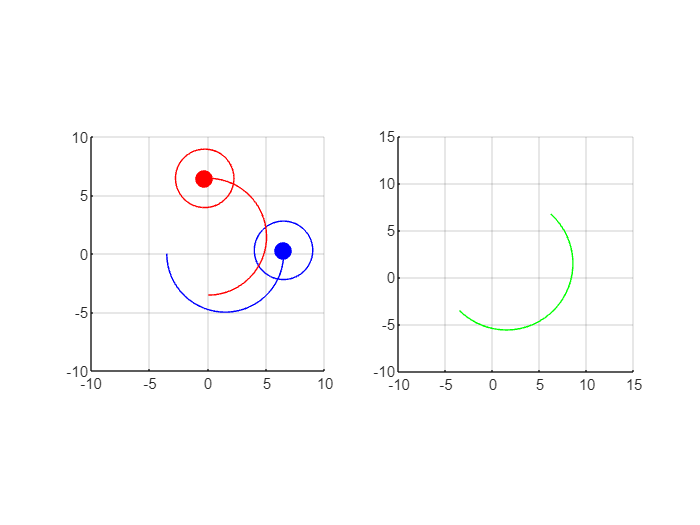


hold off;